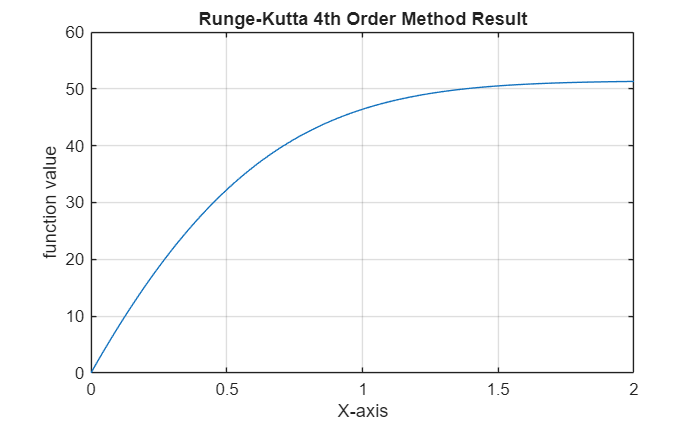

f=@(x,y) (2./sqrt(pi)).*(exp(-x.^2));
int=[0,2];
ics=[0,0];
m=200;
[xvalue,yvalue]=RungeKutta4(f,int,ics,m);
[x_ode45,y_ode45] = ode45(f,int,ics(2));

plot(xvalue,yvalue);
title('Runge-Kutta 4th Order Method Result');
xlabel('X-axis');
ylabel('function value');
grid on;

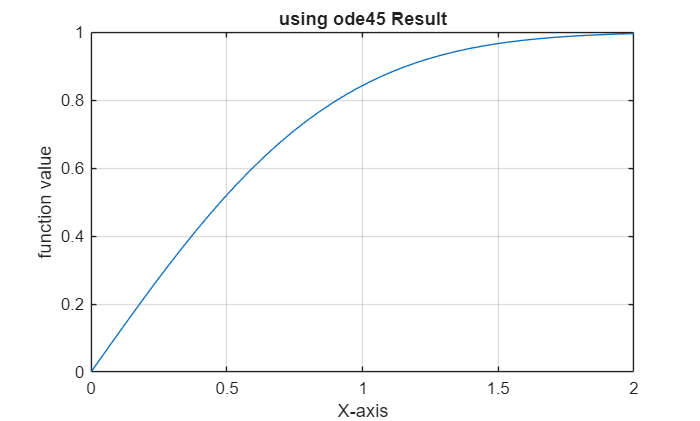


plot(x_ode45,y_ode45);
title('using ode45 Result');
xlabel('X-axis');
ylabel('function value');
grid on;

function[x,y]=RungeKutta4(f,int,ics,m)
    a=int(1);
    b=int(2);
    u=ics(1);
    y0=ics(2);
    x=linspace(a,b,m).';
    y=zeros(m-1,1);
    h=(b-a/m-1);
    [~,startIdx]=min(abs(x-u));
    y(startIdx)=y0;
    
    for k=startIdx:m-1
        k1=f(x(k),y(k));
        k2=f(x(k)+0.5*h,y(k)+0.5*h*k1);
        k3=f(x(k)+0.5*h,y(k)+0.5*h*k2);
        k4 = f(x(k) + h, y(k) + h * k3);
        y(k+1) = y(k) + (h/6) * (k1 + 2*k2 + 2*k3 + k4);
    end
end